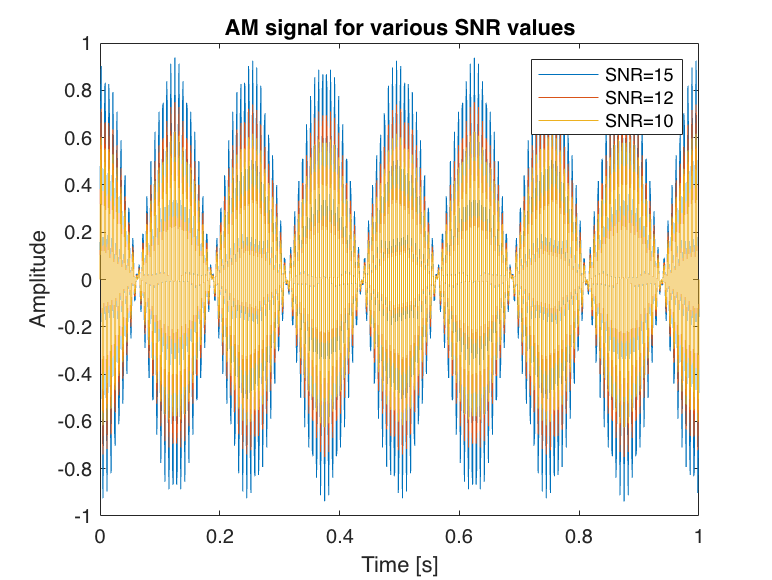

%Luis Mario Bres Castro
%Final Lab 1


sampFreq = 1024;
timeVec = 0:1/sampFreq:1;
P=struct('f0',150,'f1',4,'psi0',0);

%Generate AM Signal

H=@(x) AMSigGen_new(timeVec,x,P);

%Plot time series of SNR values for 10,12,15
snr=[10 12 15];
figure
plot(timeVec,H(snr(3)),timeVec,H(snr(2)),timeVec,H(snr(1)))
title('AM signal for various SNR values')
xlabel('Time [s]')
ylabel('Amplitude')
legend({'SNR=15','SNR=12','SNR=10'})